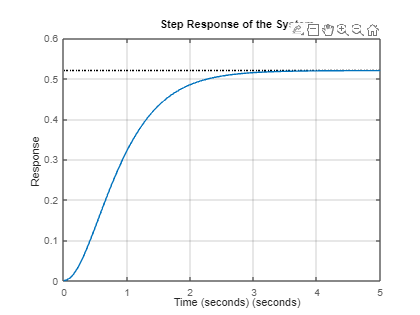

clear 
clc 

% Define the constants
k0 = 1.3;
b = 12;
a1 = 3;
a2 = 5;
a3 = 2;

% Define the numerator and denominator of the transfer function
num = k0 * [1 b];
den = conv(conv([1 a1], [1 a2]), [1 a3]);

% Create the transfer function
G = tf(num, den);

% Plot the step response
step(G);
title('Step Response of the System');
xlabel('Time (seconds)');
ylabel('Response');
grid on;